# Exercício 4

Sabendo que um processo de fabrico produz 30% de peças defeituosas e considerando a variável aleatória

X, representativa do número de peças defeituosas numa amostra de 5 peças tomadas aleatoriamente,

obtenha:

**Alínea a**

Por simulação:

i. estimativa para a função massa de probabilidade de X;

N = 1e5;
numero_lancamentos = 5 ;
x = 0:numero_lancamentos;

probs = zeros(1,numero_lancamentos + 1); 
lancamentos = rand(5,N);

lancamentos_com_defeito = lancamentos <0.30;

for i=0:numero_lancamentos
    cf = sum(lancamentos_com_defeito)==i;
    probs(i+1) = sum(cf)/N;
    
end

probs

probs =     0.1672    0.3589    0.3119    0.1319    0.0276    0.0026


ii. o gráfico representativo da função distribuição acumulada de probabilidades de X;

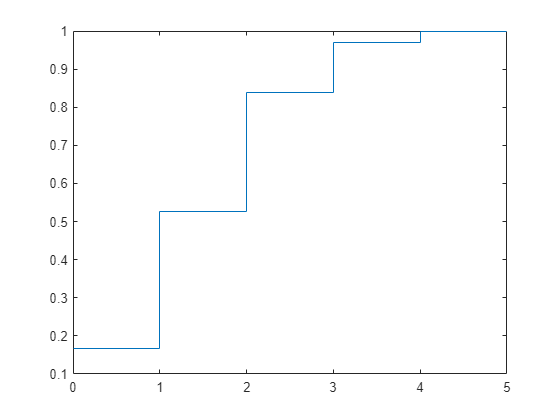

fx = cumsum(probs);

stairs(x,fx);

iii. estimativa para probabilidade de, no máximo, 2 das peças de uma amostra serem defeituosas.

prob = sum(sum(lancamentos_com_defeito) <=2)/N

prob = 0.8380

**Alínea b**

(b) Analiticamente:

i. a função distribuição acumulada de X;

probXzero = prob_teorica(0,5,0.3)

probXzero = 0.1681

probXum = prob_teorica(1,5,0.3)

probXum = 0.3601

probXdois = prob_teorica(2,5,0.3)

probXdois = 0.3087

probXtres = prob_teorica(3,5,0.3)

probXtres = 0.1323

probXquatro = prob_teorica(4,5,0.3)

probXquatro = 0.0283

probXcinco = prob_teorica(5,5,0.3)

probXcinco = 0.0024

**ii. a probabilidade de, no máximo, 2 das peças de uma amostra serem defeituosas.**

probmaxduas = probXzero + probXum + probXdois

probmaxduas = 0.8369

function p = prob_teorica(k,n,p)
    p= nchoosek(n,k)*p^k*(1-p)^(n-k); 
end